% ************************************************************
% Nombre: [Camilo Rafael] [Pérez Chaves]
% Fecha: [06/02/2025]
% Cédula: [1127575624]
% ************************************************************

# Primer punto

Dada una matriz X = (xi,j ) diseñe una funcion en Matlab para calcular


$$
S = \max_{1 \leq i \leq n} \sum_{i=1}^{n} \left| x_{ij} \right|
$$


function [M, max_suma] = maximass(a, l, i)
    M = randi(i, a, l)
    suma_filas = zeros(a, 1); 

    for k = 1:a
        suma = 0;
        for h = 1:l
            suma = suma + abs(M(k,h));
        end
        suma_filas(k) = suma;
    end

    max_suma = suma_filas(1);
    for k = 2:a
        if suma_filas(k) > max_suma
            max_suma = suma_filas(k)
        end
    end
end

maximass(3, 4, [-10,10])

M =      1    -3     0    -4
    -4     5     4     7
     3    -2    10     5


max_suma = 20

ans =      1    -3     0    -4
    -4     5     4     7
     3    -2    10     5


# Segundo punto

Utilice las formulas 8.1 y 8.2 de Burden para resolver el problema 9 pag 508. Guarde los datos en un archivo

daticos = load("daticos.txt");

%Estos son los datos necesarios para poder hallar los parametros de nuestra
%recta, que son : la pendiente y el intercepto con el eje y.

x1 = daticos(:,1);
y1 = daticos(:,2);
xc1 = x1.^2;
prod = x1.*y1;

%Aquí resolvemos las sumatorias de una forma mucho más rápida y efectiva,
%haciendo uso de la función sum(x) y no de losbucles for como hemos
%realizado comunmente en clase.
sum1=sum(xc1)

sum1 = 15034

sum2=sum(y1)

sum2 = 64.8000

sum3 = sum(prod)

sum3 = 1.7820e+03

sum4 = sum(x1)

sum4 = 546

Este primer valor hace referencia al intercepto con el eje y en la función


$$a_{0}=\frac{
  \left( \sum_{i=1}^{m} x_i^2 \right) \left( \sum_{i=1}^{m} y_i \right) - \left( \sum_{i=1}^{m} x_i y_i \right) \left( \sum_{i=1}^{m} x_i \right)
}{
  m \left( \sum_{i=1}^{m} x_i^2 \right) - \left( \sum_{i=1}^{m} x_i \right)^2
}
$$


a0 = ((sum1*sum2)-(sum3*sum4))/(20*(sum1)-(sum4)^2)

a0 = 0.4866

Este segundo resultado hace referencia la pendiente de la recta


$$a_{0}=\frac{
  m\left( \sum_{i=1}^{m} x_i  y_i\right)- \left( \sum_{i=1}^{m} y_i  \right) \left( \sum_{i=1}^{m} x_i \right)
}{
  m \left( \sum_{i=1}^{m} x_i^2 \right) - \left( \sum_{i=1}^{m} x_i \right)^2
}
$$


a1 = ((20*sum3)-(sum4*sum2))/((20*sum1)-(sum4^2))

a1 = 0.1009

Con estos dos valores somos capacez de graficar la recta

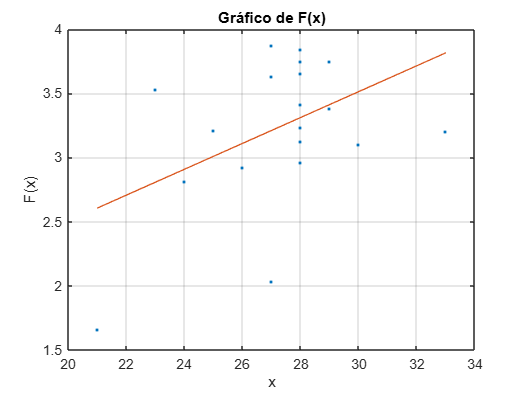

plot(x1,y1,'.')
xlabel('x');
ylabel('F(x)');
title('Gráfico de F(x)');
grid on;

y = a1*x1+a0;
hold on
plot(x1, y)

# Tercer punto

Implemente las funciones que estan en este link, las cuales se tomaron de la Wikipedia

Utilicemos la función simpson para hallar la integral definida de la función erf(x), a continuación la función simpson utilizada. 

function area = simpson(f, a, b, N)
    h = (b - a) / N;
    spar = 0;
    simp = 0;
    for k = 1:N-1
        xk = a + k * h;
        if mod(k, 2) == 0
            spar= spar + f(xk);
        else
            simp = simp + f(xk);
        end
    end
    area = (h / 3) * (f(a)+ 4*simp+2*spar+f(b));
end

Ahora si podemos definir la funcion erf(x) usando la función simpson.


$$
\[
\text{erf}(x) = \frac{2}{\sqrt{\pi}} \int_0^x e^{-t^2} \, dt
\]

\end{document}
$$


function n =erf(x)
f=@(t)exp(-t.^2);
n=(2/sqrt(pi))* (simpson(f,0,x,1000));
end

erf(1345)

ans = 0.8381

Podemos observar que la función phi(x) depende completamente de la función erf(x) es por esto que llamamos la funcion erf en el código para poder definir phi(x), así:


$$\Phi(x) = \frac{1}{2} \left[ 1 + \text{erf}\left( \frac{x}{\sqrt{2}} \right) \right]
$$


function teta = phi(x)
    teta = 1/2 * (1 + erf(x / sqrt(2)));
end

phi(62659)

ans = 8.8324

Por último, podemos definir la función F(x) de dos formas, la primera, depende de phi(x) y la segunda, depende de la función erf(x)-


$$F(x) = \Phi\left( \frac{x - u}{\sigma} \right) = \frac{1}{2} \left[ 1 + \text{erf}\left( \frac{x - u}{\sigma \sqrt{2}} \right) \right]
$$


function F = F(x, u, sigma)
    F = phi((x-u)/sigma);
end

F(250,10500,2.3)

ans = -0.0927

Ahora podemos verificar que la funcion F(x) también pued ser definida tomando la función erf(x) como parámetro.

function F_dos = F_2(x, u, sigma)
    F_dos = (1/2)*(1+erf((x-u)/(sigma*sqrt(2))));
end

Veamos que el resultado de F(x) es igual en ambos casos

F_2(250,10500,2.3)

ans = -0.0927

Para poder realizar el siguiente razonamiento es necesario investigar sobre la definición de doble factorial, para esto consulte el siguiente texto sobre combinatoria. (https://es.scribd.com/document/340655057/doble-factorial-pdf)

En resumidas palabras el doble factorial es parecido al factorial pero en vez de multiplicar por todos los valores menores que el numero se multiplica "saltando" cada 2. Es decir, el soble factorial de 6 es 6!! = 6*4*2*1

Entones definimos la siguiente función a la que recurriremos para hacer la sumatoria.

function result = doble_factorial(n)
    result = 1;   
    %Verifiquemos si el numeros es par o impar
    if mod(n, 2) == 0 
        for i = n:-2:2
            result = result * i;
        end
    else 
        for i = n:-2:1
            result = result * i;
        end
    end
end

Verifiquemos el funcionamiento de la función doble_factorial(x)

doble_factorial(6)

ans = 48


$$\Phi(x) = \frac{1}{2} + \frac{1}{\sqrt{2\pi}} \cdot e^{-\frac{x^2}{2}} \left( x + \frac{x^3}{3} + \frac{x^5}{3 \cdot 5} + \cdots + \frac{x^{2n+1}}{(2n+1)!!} + \cdots \right)
$$


function soma = sumatoria(x, n)
total_suma=0
    for p=1:2:n
        total_suma=total_suma+(x^p/doble_factorial(p));
    end
    soma=(1/2)+(1/sqrt(2*pi))*(exp(-(x^2)/2))*total_suma;
end

sumatoria(10,15)

total_suma = 0

ans = 0.5000


$$\Phi(x) \approx \frac{1}{2} + \frac{1}{\sqrt{2\pi}} \sum_{k=0}^{n} \frac{(-1)^k x^{2k+1}}{2^k k! (2k+1)}
$$


function sumas=sumatotales(x,n)

s=0;
 for k=0:n
     s=s+(((-1)^k )* (x^(2*k+1)))/(2^k)*factorial(k)*(2*k+1);
 end
 sumas=(1/2)+ (1/sqrt(2*pi))*s;
end

sumatotales(10,15)

ans = -4.9292e+39